fs = 48000;
rate = 30000;
delta_x = 1 / rate;
audio = signal2audio('data/second_waltz_reading_100_cm_volt_range_2.txt', fs, false, false);

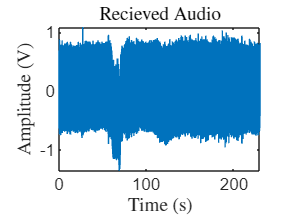

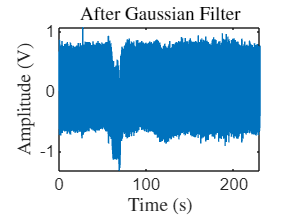

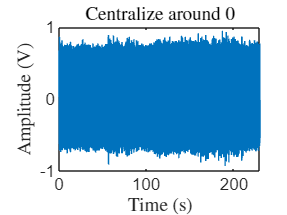

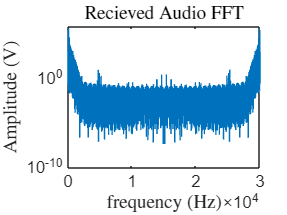

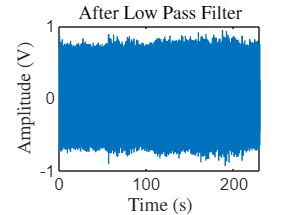

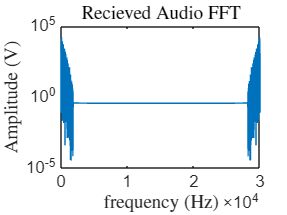

noise_frequencies =  [50, 100, 150, 200, 250, 300, 350, 400, 450, 500, 550, 600, 650, 700, 750, 800, 850, 900];
high_frequencies_threshold = 4000;
cutoff_frequency = 2903; % manually taken from the spectogram
recieved_audio = audio;
save('recieved_audio.mat', 'recieved_audio')
clean_audio = filter_audio(audio, fs, noise_frequencies, high_frequencies_threshold, cutoff_frequency, delta_x, true);

function audio = signal2audio(signal_path, fs, play_audio, gen_plot)
    % read data
    data_dec = readtable(signal_path, 'FileType', 'delimitedtext');
    time = data_dec.Time;
    voltage = data_dec.Dev1_ai0;
    time = time(1400: end - 1000);
    voltage = voltage(1400: end - 1000);
    voltage = voltage - mean(voltage);
    audio = voltage * 100;
    if play_audio
        sound(audio, fs)
    end
    if gen_plot
        % plot current result
        plot_signal(voltage, "Recieved Audio", delta_x)
    end
    audiowrite('recieved_audio.wav', audio, fs);
end

function clean_audio = filter_audio(audio, fs, noise_frequencies, high_frequencies_threshold, cutoff_frequency, delta_x, play_audio)
    num_samples = length(audio);
    plot_signal(audio, "Recieved Audio", delta_x);
    % gaussian filter
    gaussian_cleaned_audio = gaussian_filter(audio, delta_x);

   % zero mean filter - correct serios flactuations
   gaussian_cleaned_audio = centralize_around_zero(gaussian_cleaned_audio, 10000);
   plot_signal(gaussian_cleaned_audio, "Centralize around 0", delta_x)

    f = 1 / (delta_x * num_samples) * linspace(0, (num_samples - 1), num_samples);
    audio_fft = fft(gaussian_cleaned_audio) / 2 * pi;
    plot_fft(audio_fft, f)
    
    % Low Pass Filter
    filter_order = 1e4; % Adjust as needed
    lowpass_filter = designfilt('lowpassfir', 'FilterOrder', filter_order, 'CutoffFrequency', cutoff_frequency, 'SampleRate', fs);
    filtered_audio = filter(lowpass_filter, gaussian_cleaned_audio);
    plot_signal(filtered_audio, "After Low Pass Filter", delta_x)
    
    % Remove Known Low Frequency Noise Sources
    audio_fft = fft(filtered_audio) / 2 * pi;
    cleaned_fft = audio_fft;
    for nf = noise_frequencies
        nf_bound = f(find(f < (nf + 5)));
        nf_bound_indices = find(nf_bound > (nf - 5));
        cleaned_fft(nf_bound_indices) = (cleaned_fft(nf_bound_indices - length(nf_bound_indices)) + cleaned_fft(nf_bound_indices + length(nf_bound_indices))) / 2;
        cleaned_fft(end - nf_bound_indices) = (cleaned_fft(end - (nf_bound_indices - length(nf_bound_indices))) + cleaned_fft(end - (nf_bound_indices + length(nf_bound_indices)))) / 2;
    end

    % Visualize and play results
    plot_fft(cleaned_fft, f)
    clean_audio = real(ifft(cleaned_fft));
    plot_signal(clean_audio, "Known Noise Frequency Removed", delta_x)
    if play_audio
          sound(real(clean_audio), fs)
    end
    audiowrite('cleaned_audio.wav', real(clean_audio), fs);
    save('clean_audio.mat', 'clean_audio')
end

function cleaned_audio = gaussian_filter(audio, delta_x)
    % down sample over sampled frequencies
    w = gausswin(40);
    w = w/sum(w);
    cleaned_audio = filter(w, 1, audio);
    plot_signal(cleaned_audio, "After Gaussian Filter",delta_x)
end

function centralized_signal = centralize_around_zero(signal, window_size)
    centralized_signal = zeros(size(signal));
    N = length(signal);
    for i = 1:N
        % Determine the window range
        window_start = max(1, i - floor(window_size / 2));
        window_end = min(N, i + floor(window_size / 2));
        
        % Extract the window segment
        window_segment = signal(window_start:window_end);
        
        % Compute the mean of the window segment
        window_mean = mean(window_segment);
        
        % Subtract the mean from the current sample
        centralized_signal(i) = signal(i) - window_mean;
    end
end

function plot_fft(audio_fft, frequencies)
    figure
    plot(frequencies, audio_fft)
    set(gca, 'yscale', 'log');
    xlabel("frequency (Hz)", Interpreter="latex");
    ylabel("Amplitude (V)", Interpreter="latex");
    title("Recieved Audio FFT", Interpreter="latex");
end

function plot_signal(signal, header, delta_x)
    figure
    num_samples = length(signal);
    t = linspace(0, delta_x * (num_samples - 1), num_samples);
    plot(t, signal);
    xlabel("Time (s)", Interpreter="latex");
    ylabel("Amplitude (V)", Interpreter="latex");
    title(header, Interpreter="latex");
end